%% 初始设置
close all,clear,clc,
tic,
% 初始化仿真时间区间
t0 = 0.0;
tf = 10.0;

%初始条件
x10 = 5;
x20 = -6;
state0 = [x10;x20]; %状态向量初值

%% 仿真
[tout,stateout] = ode45(@statequation01, [t0, tf], state0);

%输出t0-tf每一时刻的状态
x1out = stateout(:, 1);
x2out = stateout(:, 2);

y1out = x1out + 2*x2out;
y2out = 3*x1out - x2out;

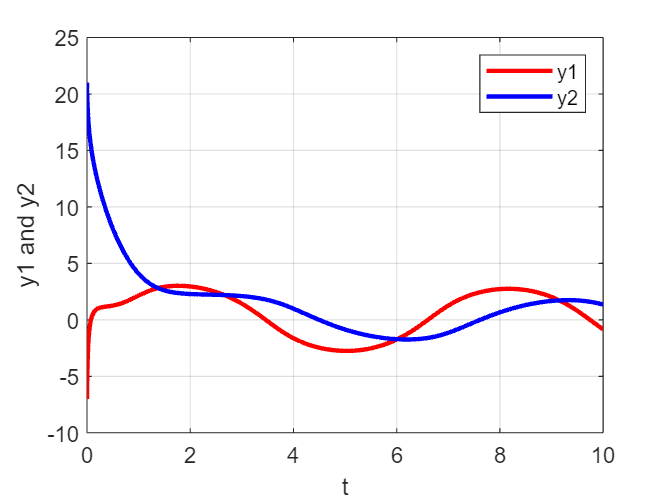

%% 绘图
%画图1
figure(1);
plot(tout, y1out, "r", tout, y2out, "b", 'LineWidth', 2);
ylabel('y1 and y2');
xlabel('t');
grid on;
legend("y1","y2");

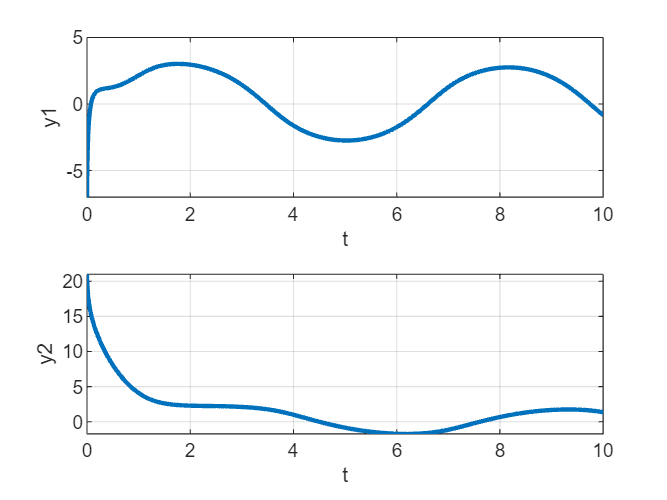


%画图2
figure(2);
subplot(2,1,1);
plot(tout, y1out, 'LineWidth', 2);
xlabel('t');ylabel('y1');
grid on;hold on;

subplot(2,1,2);
plot(tout, y2out, 'LineWidth', 2);
xlabel('t');ylabel('y2');
grid on;hold on;


toc

历时 0.432442 秒。


function statedot=statequation01(t,state)
% 函数
% x = [x1;x2]
x1 = state(1);
x2 = state(2);

%状态方程
u = 5*sin(t);
x1dot = -x1 + x2;
x2dot = -x1 - 3*x2 - x2^3 + u;

%输出得到的四个状态量
statedot=[x1dot;x2dot];
end